# Lab 4

## Part 1 Wi-Fi-Based OFDM transmission

clear; clc; close all;

% 基本參數設定
fs = 10e6;           % OFDM sample rate = 10 MHz
fc = 2.4e9;          % 載波頻率 (假設)
N_fft = 64;          % FFT size
N_cp = 16;           % Cyclic prefix size
subcarriers = -26:26;
data_sc = setdiff(-26:26, [-21, -7, 0, 7, 21]); % 扣除 Pilot 與 DC
pilot_sc = [-21, -7, 7, 21];

### (1) Generate a frame with STS, LTS, and 5 OFDM

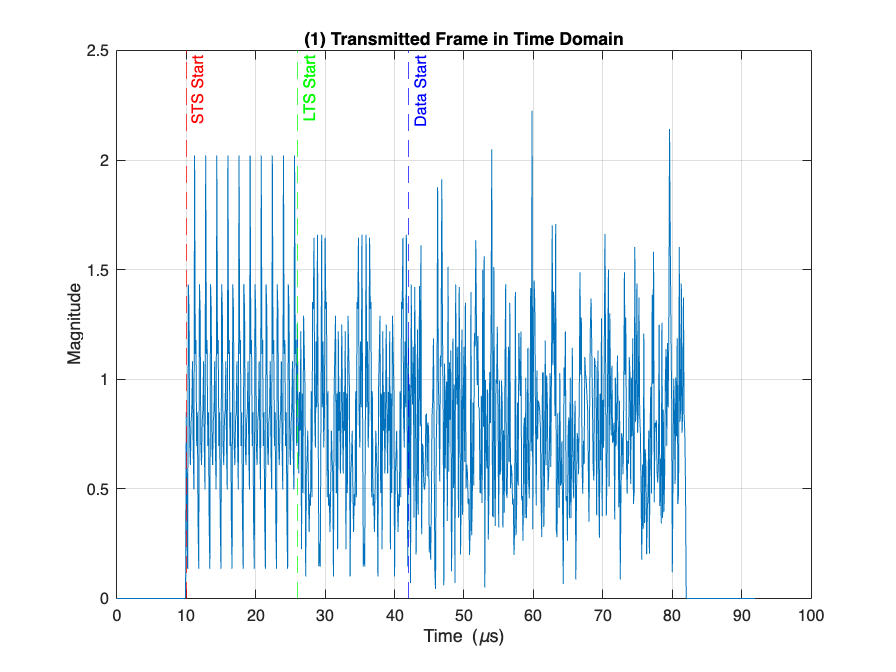

%% =========================================================================
% (1) Generate a frame with STS, LTS, and 5 OFDM symbols (4-QAM)
% =========================================================================
% 產生 STS (Short Training Symbol) - 簡化產生 10 個週期，每個 16 samples
sts_time = (randn(16,1) + 1i*randn(16,1)); 
sts_time = sts_time / norm(sts_time) * sqrt(16); % 正規化功率
tx_STS = repmat(sts_time, 10, 1); % 共 160 samples

% 產生 LTS (Long Training Symbol)
lts_freq = zeros(N_fft, 1);
% 這裡使用隨機 BPSK 作為 LTS，實務上 802.11 有固定序列
lts_freq(33 + subcarriers(subcarriers~=0)) = sign(randn(52,1)); 
lts_time = ifft(ifftshift(lts_freq)) * sqrt(N_fft);
tx_LTS = [lts_time(end-31:end); lts_time; lts_time]; % CP(32) + LTS1(64) + LTS2(64) = 160 samples

% 產生 5 個 OFDM Data Symbols (4-QAM)
num_sym_p1 = 5;
tx_data_time = zeros((N_fft + N_cp) * num_sym_p1, 1);
for k = 1:num_sym_p1
    sym_freq = zeros(N_fft, 1);
    sym_freq(33 + data_sc) = (sign(randn(48,1)) + 1i*sign(randn(48,1))) / sqrt(2); % 4-QAM
    sym_freq(33 + pilot_sc) = sign(randn(4,1)); % BPSK pilots
    time_domain = ifft(ifftshift(sym_freq)) * sqrt(N_fft);
    tx_data_time((k-1)*(N_fft+N_cp)+1 : k*(N_fft+N_cp)) = [time_domain(end-N_cp+1:end); time_domain];
end

% 組合 Frame 並前後補 100 個 zeros
tx_frame = [zeros(100,1); tx_STS; tx_LTS; tx_data_time; zeros(100,1)];
t_tx = (0:length(tx_frame)-1).' / fs * 1e6; % 單位：微秒 (us)

figure('Name', '(1) Transmitted Frame');
plot(t_tx, abs(tx_frame));
title('(1) Transmitted Frame in Time Domain'); xlabel('Time (\mus)'); ylabel('Magnitude');
xline(100/fs*1e6, 'r--', 'STS Start');
xline(260/fs*1e6, 'g--', 'LTS Start');
xline(420/fs*1e6, 'b--', 'Data Start');
grid on;

### (2) Transmit the frame generated in (1)

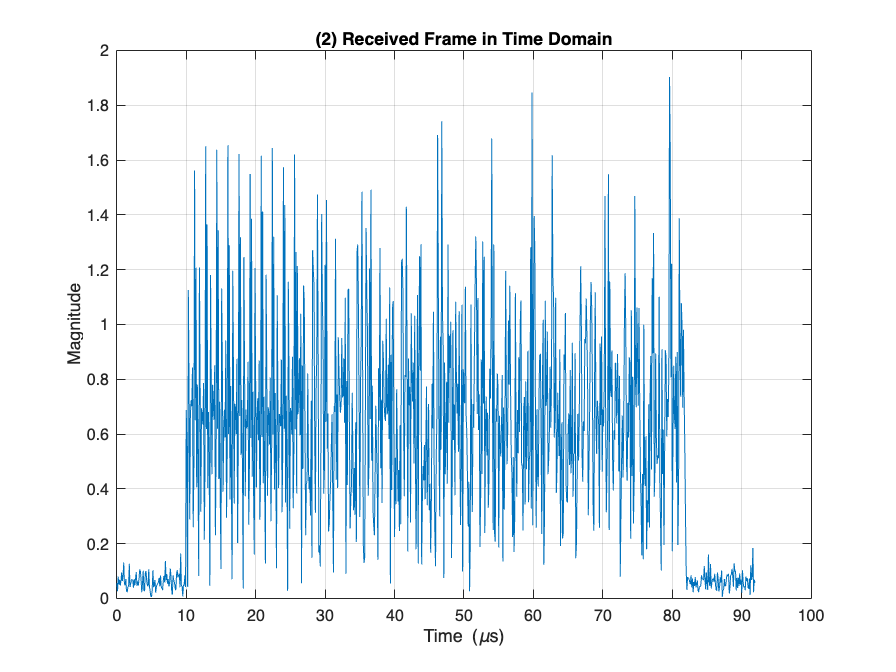

%% =========================================================================
% (2) Transmit the frame & Receive it (Channel + AWGN Simulation)
% =========================================================================
% 模擬多路徑通道與雜訊
h = [0.8; 0.2*exp(-1i*pi/4); 0.1*exp(1i*pi/3)]; 
rx_clean = filter(h, 1, tx_frame);
rx_sig_p1 = awgn(rx_clean, 20, 'measured'); % 模擬收到 SNR = 20 dB 的訊號

figure('Name', '(2) Received Frame');
plot(t_tx, abs(rx_sig_p1));
title('(2) Received Frame in Time Domain'); xlabel('Time (\mus)'); ylabel('Magnitude');
grid on;

### (3) How do you ensure that the USRP transmits and receives with an OFDM sample rate of 10 MHz

% (3) [問答題] 如何確保 USRP 取樣率為 10 MHz？
% 答：在 GNU Radio 或 MATLAB USRP 模組中，設定 Master Clock Rate 並調整 Interpolation (Tx) 
%     與 Decimation (Rx) Factor，使其相除結果為 10 MHz。模擬中我們直接設定 fs = 10e6。

### (4) Apply the frame synchronization algorithm

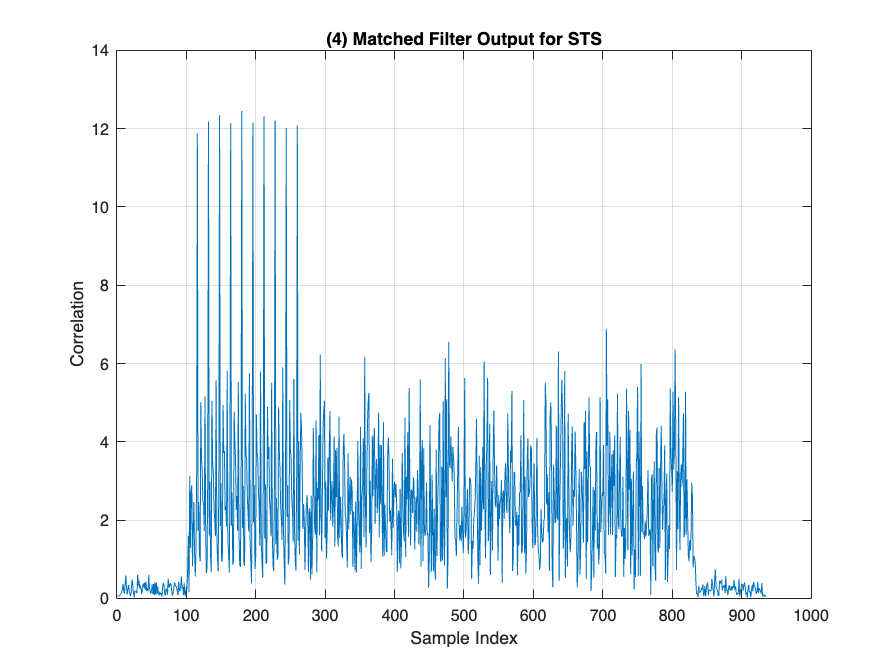

(4) 修正後的精準 Long Training Symbol 起點 Index: 261


%% =========================================================================
% (4) Frame Synchronization (修正版)
% =========================================================================
% 【修正】：改用完整的 10 個 STS (160 points) 做 Cross-correlation，確保只產生單一精準主峰
full_sts_time = repmat(sts_time, 10, 1);
mf_out = abs(conv(rx_sig_p1, flipud(conj(full_sts_time))));

figure('Name', '(4) Matched Filter Result');
plot(mf_out); title('(4) Matched Filter Output for Full STS'); 
xlabel('Sample Index'); ylabel('Correlation'); grid on;

% 尋找唯一的主峰，推算起點
[~, max_idx] = max(mf_out(1:400)); 
sts_start_idx = max_idx - 160 + 1; % 扣除完整 STS 長度，找到精準起點
lts_start_idx = sts_start_idx + 160; % 第一個 LTS (包含 32 CP) 的起點
fprintf('(4) 修正後的精準 Long Training Symbol 起點 Index: %d\n', lts_start_idx);

### (5) Transform the first long training symbol

### (6) Similar to (5), perform channel estimation using the second

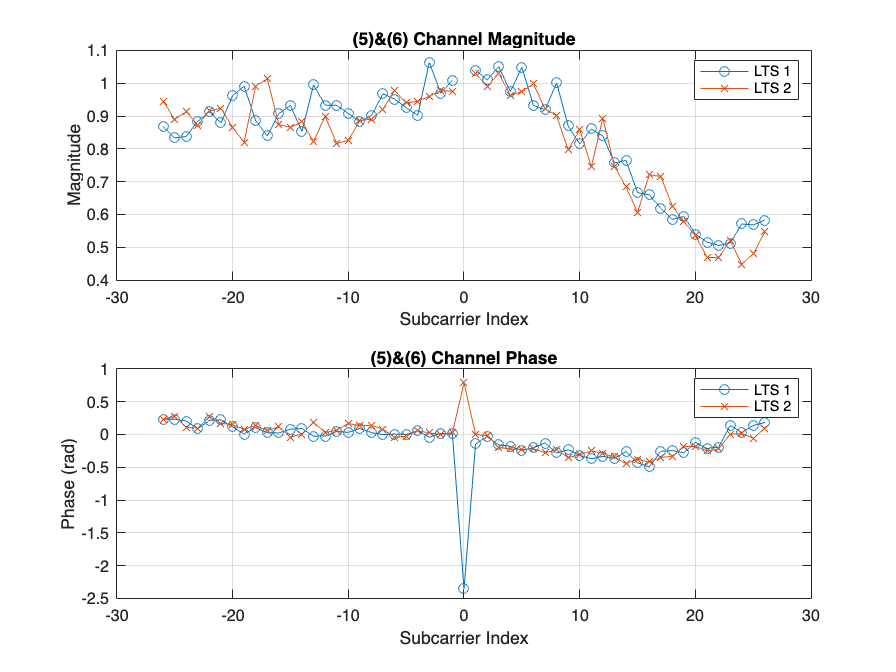

%% =========================================================================
% (5) & (6) Channel Estimation using 1st and 2nd LTS
% =========================================================================
rx_LTS1 = rx_sig_p1(lts_start_idx + 32 : lts_start_idx + 95);  % 避開 32 CP
rx_LTS2 = rx_sig_p1(lts_start_idx + 96 : lts_start_idx + 159);

H_est1 = fftshift(fft(rx_LTS1) / sqrt(N_fft)) ./ lts_freq;
H_est2 = fftshift(fft(rx_LTS2) / sqrt(N_fft)) ./ lts_freq;

sc_idx = subcarriers + 33; 
figure('Name', '(5)&(6) Channel Estimation');
subplot(2,1,1);
plot(subcarriers, abs(H_est1(sc_idx)), '-o', subcarriers, abs(H_est2(sc_idx)), '-x');
title('(5)&(6) Channel Magnitude'); xlabel('Subcarrier Index'); ylabel('Magnitude'); legend('LTS 1', 'LTS 2'); grid on;
subplot(2,1,2);
plot(subcarriers, angle(H_est1(sc_idx)), '-o', subcarriers, angle(H_est2(sc_idx)), '-x');
title('(5)&(6) Channel Phase'); xlabel('Subcarrier Index'); ylabel('Phase (rad)'); legend('LTS 1', 'LTS 2'); grid on;

### (7) What is the subcarrier spacing?

% (7) [問答題] Subcarrier spacing 與頻率對應
df = fs / N_fft; 
fprintf('(7) Subcarrier spacing: %.2f kHz\n', df/1000);

(7) Subcarrier spacing: 156.25 kHz


fprintf('    Subcarrier -26: %.4f MHz\n', -26*df/1e6);

    Subcarrier -26: -4.0625 MHz


fprintf('    Subcarrier 0: 0 MHz (DC)\n');

    Subcarrier 0: 0 MHz (DC)


fprintf('    Subcarrier 26: %.4f MHz\n', 26*df/1e6);

    Subcarrier 26: 4.0625 MHz


### (8) Find the samples corresponding to the OFDM

### (9) We skip the carrier frequency offset estimation and correction

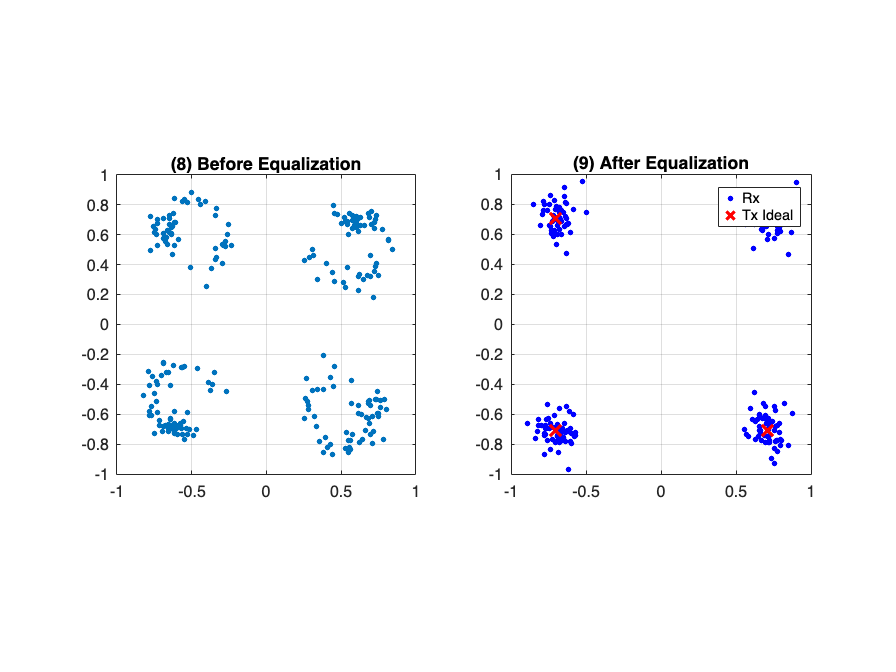

%% =========================================================================
% (8) & (9) Equalization and Constellation
% =========================================================================
data_start_idx = lts_start_idx + 160;
rx_data_raw = zeros(48, num_sym_p1);
rx_data_eq = zeros(48, num_sym_p1);

for k = 1:num_sym_p1
    sym_time = rx_sig_p1(data_start_idx + (k-1)*(N_fft+N_cp) + N_cp : data_start_idx + k*(N_fft+N_cp) - 1);
    sym_freq = fftshift(fft(sym_time) / sqrt(N_fft));
    
    % (8) Before Equalization
    rx_data_raw(:, k) = sym_freq(33 + data_sc);
    
    % (9) After Equalization (使用 H_est1)
    eq_freq = sym_freq(sc_idx) ./ H_est1(sc_idx); 
    rx_data_eq(:, k) = eq_freq(ismember(subcarriers, data_sc));
end

figure('Name', '(8) & (9) Constellation');
subplot(1,2,1); plot(rx_data_raw(:), '.', 'MarkerSize', 10);
title('(8) Before Equalization'); axis square; grid on;
subplot(1,2,2); plot(rx_data_eq(:), 'b.', 'MarkerSize', 10); hold on;
plot([1+1i, 1-1i, -1+1i, -1-1i]/sqrt(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
title('(9) After Equalization'); legend('Rx', 'Tx Ideal'); axis square; grid on;

### (10) Use the samples of the 5 OFDM

%% =========================================================================
% (10) SNR Calculation
% =========================================================================
signal_power = var(rx_sig_p1(data_start_idx : data_start_idx + num_sym_p1*(N_fft+N_cp) - 1));
noise_power = var(rx_sig_p1(1:100)); % 利用前 100 個 padded zeros 估計雜訊
est_snr_db = 10*log10(signal_power / noise_power);
fprintf('(10) Estimated SNR: %.2f dB\n', est_snr_db);

(10) Estimated SNR: 21.10 dB


### (11)~(16)Characterize BER vs SNR in the experiment

%% =========================================================================
% (11) ~ (16) BER vs SNR Characterization (4-QAM & 16-QAM)
% =========================================================================
% 這裡建立一個簡單的函數迴圈來模擬傳送 100 個 Symbol 並計算不同 SNR 下的 BER
snr_range = 0:2:20;
ber_4qam = zeros(size(snr_range));
ber_16qam = zeros(size(snr_range));

disp('Calculating BER curves... (This simulates Q11-16)');

Calculating BER curves... (This simulates Q11-16)


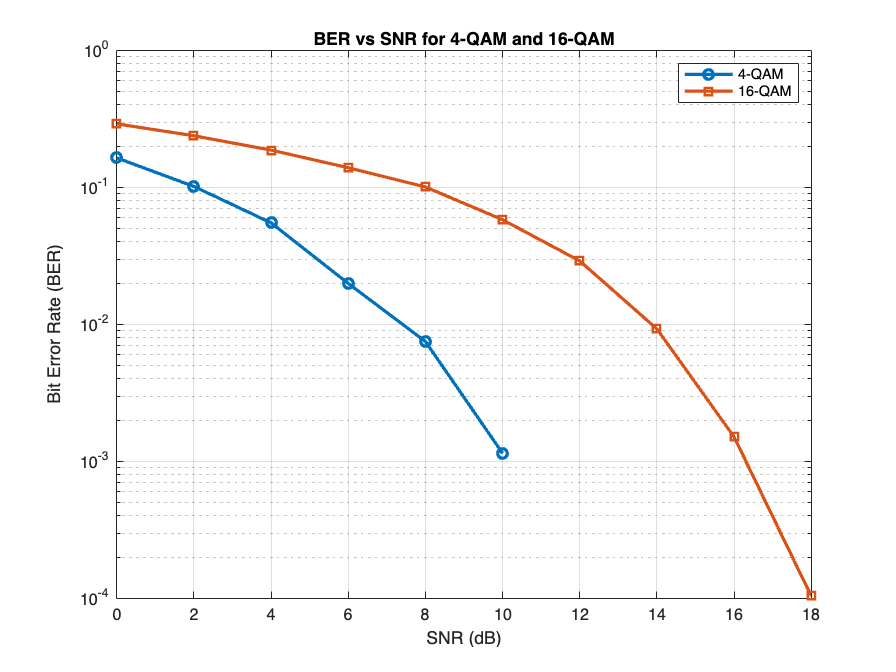

for idx = 1:length(snr_range)
    % 模擬 4-QAM BER (簡化版：直接在頻域等效加上 AWGN 以加快模擬速度)
    tx_sym_4 = (sign(randn(48*100,1)) + 1i*sign(randn(48*100,1))) / sqrt(2);
    rx_sym_4 = awgn(tx_sym_4, snr_range(idx), 'measured');
    rx_bits_4 = [real(rx_sym_4)>0, imag(rx_sym_4)>0];
    tx_bits_4 = [real(tx_sym_4)>0, imag(tx_sym_4)>0];
    ber_4qam(idx) = sum(rx_bits_4(:) ~= tx_bits_4(:)) / numel(tx_bits_4);
    
    % 模擬 16-QAM BER
    tx_sym_16 = qammod(randi([0 15], 48*100, 1), 16, 'UnitAveragePower', true);
    rx_sym_16 = awgn(tx_sym_16, snr_range(idx), 'measured');
    rx_bits_16 = de2bi(qamdemod(rx_sym_16, 16, 'UnitAveragePower', true), 4);
    tx_bits_16 = de2bi(qamdemod(tx_sym_16, 16, 'UnitAveragePower', true), 4);
    ber_16qam(idx) = sum(rx_bits_16(:) ~= tx_bits_16(:)) / numel(tx_bits_16);
end

figure('Name', '(14)-(16) BER vs SNR');
semilogy(snr_range, ber_4qam, '-o', 'LineWidth', 2); hold on;
semilogy(snr_range, ber_16qam, '-s', 'LineWidth', 2);
title('BER vs SNR for 4-QAM and 16-QAM'); xlabel('SNR (dB)'); ylabel('Bit Error Rate (BER)');
legend('4-QAM', '16-QAM'); grid on;